# Problema 1

function [a, phi] = mmp_general(x, y, baza)
% INPUT:
%   x, y  – vectori de date (m puncte)
%   baza  – celula de functii (ex: {@(x) 1, @(x) x, @(x) x.^2})
%
% OUTPUT:
%   a     – vectorul coeficientilor
%   phi   – functia aproximanta (phi(t) ≈ f(t))

    n = length(baza);  % numarul de functii baza

    % Construim sistemul normal: G * a = b
    G = zeros(n);
    b_vec = zeros(n, 1);

    for i = 1:n
        for j = 1:n
            G(i, j) = sum(baza{i}(x) .* baza{j}(x));
        end
        b_vec(i) = sum(y .* baza{i}(x));
    end

    a = G \ b_vec;

    % Functie aproximanta
    phi = @(t) sum(cell2mat(arrayfun(@(k) a(k) * baza{k}(t), 1:n, 'UniformOutput', false)));
end


x = [-1, 2, -3];      % Puncte discrete
y = [1, 3, 9];        % f(x) = x^2

n = 2;  % Gradul maxim al polinomului

% Construim baza {1, x, x^2}
baza = cell(1, n+1);
for k = 0:n
    baza{k+1} = @(x) x.^k;
end

[a, phi] = mmp_general(x, y, baza);
fprintf("Coeficientii aproximantului:\n"); disp(a);

Coeficientii aproximantului:
   -0.2000
   -0.2667
    0.9333



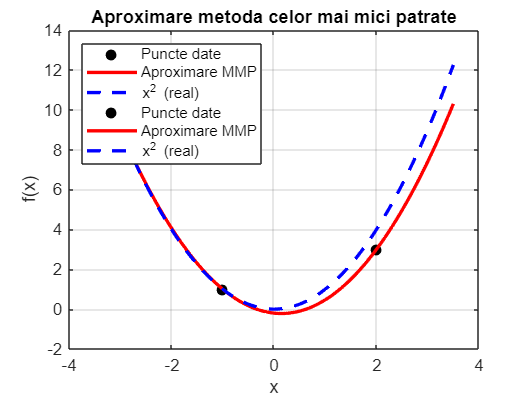


% Grafic
xx = linspace(-3.5, 3.5, 200);
yy_aprox = polyval(flip(a'), xx);
yy_real = xx.^2;

plot(x, f, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Puncte date'); hold on;
plot(xx, yy_aprox, 'r-', 'LineWidth', 2, 'DisplayName', 'Aproximare MMP');
plot(xx, yy_real, 'b--', 'LineWidth', 2, 'DisplayName', 'x^2 (real)');
legend('Location', 'northwest');
xlabel('x'); ylabel('f(x)');
title('Aproximare metoda celor mai mici patrate');
grid on;